format long
syms f(x) X
f(x) = x^2-9;    % x is automatically created once f(x) is created.
diffF = diff(f,x)

$$diffF(x) = 2\,x$$

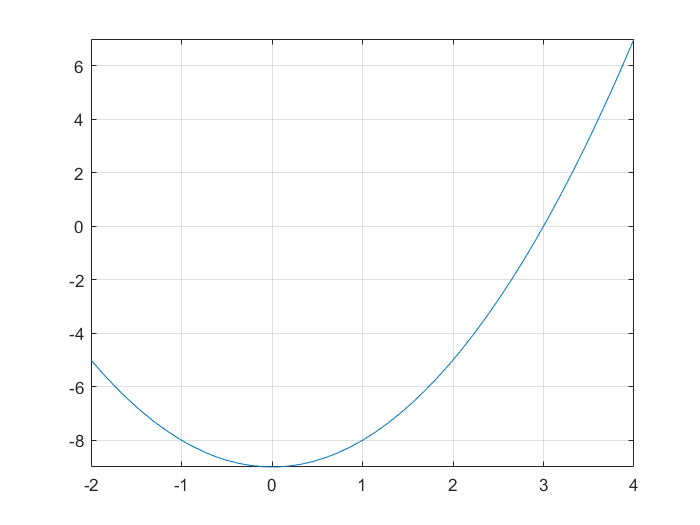

fplot(f, [-2 4])  
grid on

digitsOld = digits(7);

M = [];                 % Matrix to store all values. Non-symbolic.
X = 1                  % Starting value for the iteration. 

X =      1


% X will ve updated after every iteration.
i = 1;
while (abs(vpa(f(X)))> 1e-4)
    if diffF(X) <= 1e-6
        disp('Derivative is too small.')
        break
    end
    X = vpa(X - f(X)/diffF(X))      % Updating X. 
    M(i) = X;    % Storing the updated value in an array for later use.
    if i>=3
        if(abs(M(i)-M(i-1))> abs(M(i-1)-M(i-2)))
            disp('The iteration does not converge')
            break
        end
    end
    i = i + 1;
end

$$X = 5.0$$

$$X = 3.4$$

$$X = 3.023529$$

$$X = 3.000092$$

$$X = 3.0$$

round(M,6)

ans =    5.000000000000000   3.400000000000000   3.023529000000000   3.000092000000000   3.000000000000000


eqns = f(x)==0;
Exact_Solution = vpasolve(eqns,x)

$$Exact\_Solution = \left(\begin{array}{c} -3.0\\ 3.0 \end{array}\right)$$

Error = abs(Exact_Solution(1) - M');
Relative_Error = Error/Exact_Solution(1);
Table = vpa([M' Error Relative_Error])

$$Table = \left(\begin{array}{ccc} 5.0 & 8.0 & -2.666667\\ 3.4 & 6.4 & -2.133333\\ 3.023529 & 6.023529 & -2.007843\\ 3.000092 & 6.000092 & -2.000031\\ 3.0 & 6.0 & -2.0 \end{array}\right)$$

% Finding order of convergence
format long 
%M = [0.3243 .1277 0.0259 0.002327 0.00004467];
n = length(Error)-1

n =      4


r = log(Error(1:n))

$$r = \left(\begin{array}{c} 2.079442\\ 1.856298\\ 1.795673\\ 1.791775 \end{array}\right)$$

s = log(Error(2:n+1))

$$s = \left(\begin{array}{c} 1.856298\\ 1.795673\\ 1.791775\\ 1.791759 \end{array}\right)$$

sumr=0.00; sums = 0.00; sumr2 = 0.00; sumrs=0.00;
for i = 1:n
    sumr = sumr+r(i);
    sumr2 = sumr2 + r(i)^2;
    sums = sums + s(i);
    sumrs = sumrs + r(i)*s(i);
end
Order_of_Convergence = (sumr*sums-n*sumrs)/(sumr^2-n*sumr2)

$$Order\_of\_Convergence = 0.2303611$$